## Supplementary 2 

clear all; close all; clc;

%add the source data
addpath 'path\to\data_source';
addpath 'path\to\INTHIS\DataAnalysis';

%load 
load S.mat;
load('t.mat');
load('X.mat');

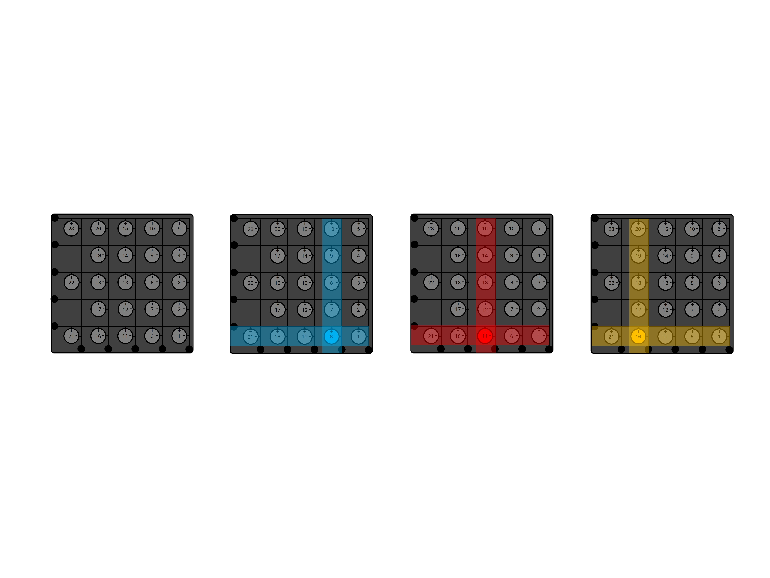

%read the images
img=struct;
img.img0=imread("subfigures\state0.jpg");
img.img6=imread("subfigures\state1.jpg");
img.img11=imread("subfigures\state2.jpg");
img.img16=imread("subfigures\state3.jpg");

figure; tiledlayout(1,4,'TileSpacing','compact','Padding','compact');
nexttile; imshow(img.img0);
nexttile; imshow(img.img6);
nexttile; imshow(img.img11);
nexttile; imshow(img.img16);

## Load the data

%get the indentation
Sn="S6";
Tn="T16";

%get the spike data relative to this ind
fbgs=S.(Sn).(Tn).FBGs; fbgs(:,2:end)=fbgs(:,2:end)-fbgs(1,2:end);
neurons=S.(Sn).(Tn).Neurons; neurons(:,2)=neurons(:,2)+1; %from labview/arduino to matlab!
motors=S.(Sn).(Tn).Motors; motors(:,2)=motors(:,2)+1; 
roi=S.(Sn).(Tn).ROI;
ind=S.(Sn).(Tn).Ind;

%timing limits
tmin=min(neurons(:,1))-1;
limits=[0 max(neurons(:,1))+1-tmin];
motors(:,1)=motors(:,1)-tmin;


%extract and process data
ids=motors(:,2);
allspikes=motors(:,1); 

## Create the signals

%timing issues
tc=0.0001; %s
tau=0.010; %s
g=1;
a=tc/(tau+tc);
a=0.0005;
T=0.5; %s
N=T/tc;
time=(1:tc:1+T)'; time(end)=[]; %ms

%create the 23 signals
ys=zeros(N,23);
for i=1:23

    %compute spiketimes
    spiketimes=motors(motors(:,2)==i,1);

    %signals containers
    y=zeros(N,1);
    x=zeros(N,1);
    [~,closestIndex] = min(abs(time-spiketimes'));
    x(closestIndex)=1;

    %filtering operation
    for n=1:(N-1)    
        y(n+1)=g*a*x(n)+(1-a)*y(n);
    end
    y(1)=0; y(end)=0;
    
    %save the signal
    ys(:,i)=y;
end

## Base figure

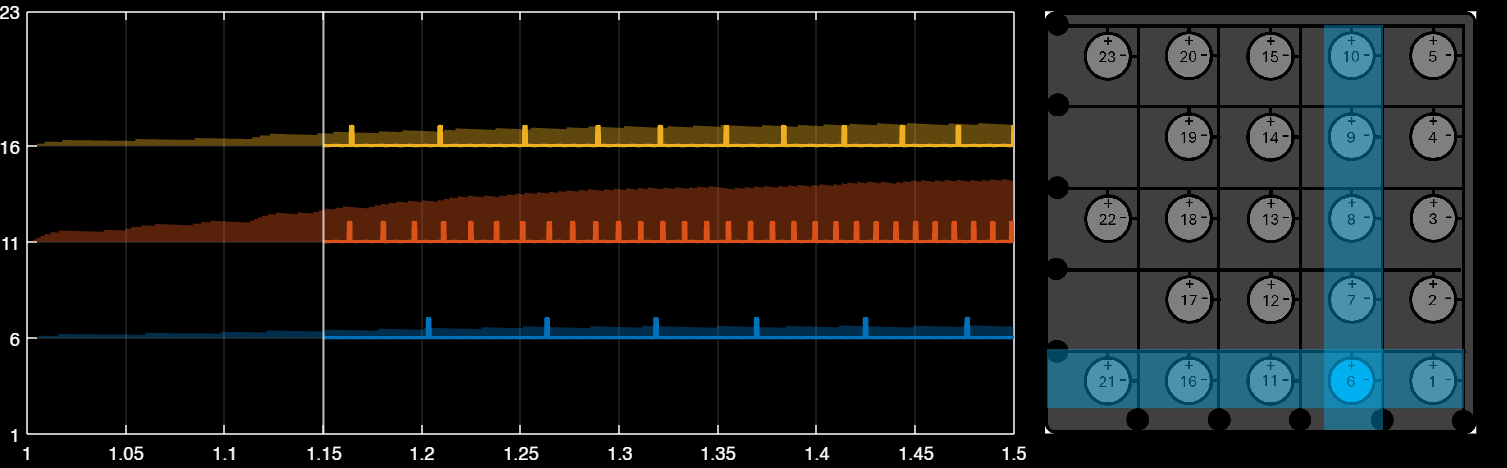

base=figure('Units','centimeters','Position',[0 2 29 9]);
tiledlayout(1,3,"TileSpacing","none","Padding","none");
        
%the first tile
nexttile([1 2]);
hold on;

%the point at which we are
xtresh=1.15;
xline(xtresh,'Color','w','LineWidth',1);


%figure settings
visualizerscale=2;
grid on; 
C=colororder;
ylim([1 23]);
yticks([1 6 11 16 23]);
xlim([1 1.5]);
box on;

%recall and plot the signals
c=0;
for i=1:23

    %signals containers
    y=ys(:,i);

    %result
    timep=time;
    yp=y;
    yp(1)=0; yp(end)=0;
    if any(y)
        c=c+1;
        fill(timep,visualizerscale*100*yp+i,0,'FaceColor',C(c,:),'FaceAlpha',0.4,'EdgeColor','none');
    end
end

%plot the pulses
ix=time>xtresh;
plot(time(ix),X(ix,1)+6,"Color",C(1,:),'LineWidth',2);
plot(time(ix),X(ix,2)+11,"Color",C(2,:),'LineWidth',2);
plot(time(ix),X(ix,3)+16,"Color",C(3,:),'LineWidth',2);
recolorfig(backcolor='k',scriptcolor='w');

hold off;
nexttile;
axis off;
imshow(img.(sprintf("img%d",6)));
recolorfig(backcolor='k',scriptcolor='w');

## Create the video using the base figure

%for this figure, every sample of the signal, acquired with 0.1 ms sample
%time, is now saved with a 100x scale--> with 10 ms sample time. So what
%lasted 0.5 s now lasts 0.5x100=50s

%with the above configuration it means that we must run the video at
%FrameRate=100 Hz (0.01 s)
%FrameCount=5000

%if this is too much, setting to the half
%so, downsample of 2 everything: X, time, and
%FrameRate=50 Hz (0.02 s)
%FrameCount=2500

%collapse X to 1D
Xc=X;
tc=t;

Xc(Xc(:,1)==1,1)=6;
Xc(Xc(:,2)==1,1)=11;
Xc(Xc(:,3)==1,1)=16;
Xc=Xc(:,1);

%downsample and manage
dsrate=1;
Xc=Xc(1:dsrate:end,:);
tc=tc(1:dsrate:end);
FR=100/dsrate; %Hz
FC=5000/dsrate;

v=VideoWriter('v.mp4','MPEG-4');
v.FrameRate=FR;

open(v);
tic;
xtresh=1;
counter=0;
for i=1:FC
        %base figure
        base=figure('Units','centimeters','Position',[0 2 29 9],'Visible','off');
        tiledlayout(1,3,"TileSpacing","none","Padding","none");
        
        %the first tile
        nexttile([1 2]);
        hold on;

        %the point at which we are
        xtresh=tc(i);
        xline(xtresh,'Color','w','LineWidth',1);

        %figure settings
        visualizerscale=2;
        grid on; 
        C=colororder;
        ylim([1 23]);
        yticks([1 6 11 16 23]);
        xlim([1 1.5]);
        box on;

        %recall and plot the signals
        c=0;
        for j=1:23

            %signals containers
            y=ys(:,j);

            %result
            timep=time;
            yp=y;
            yp(1)=0; yp(end)=0;
            if any(y)
                c=c+1;
                fill(timep,visualizerscale*100*yp+j,0,'FaceColor',C(c,:),'FaceAlpha',0.4,'EdgeColor','none');
            end
        end

        %plot the pulses
        ix=time>xtresh;
        plot(time(ix),X(ix,1)+6,"Color",C(1,:),'LineWidth',2);
        plot(time(ix),X(ix,2)+11,"Color",C(2,:),'LineWidth',2);
        plot(time(ix),X(ix,3)+16,"Color",C(3,:),'LineWidth',2);
        recolorfig(backcolor='k',scriptcolor='w');
        hold off;

        nexttile;
        hold on;
        
        name=(sprintf("img%d",Xc(i)));
        imshow(img.(name));
        recolorfig(backcolor='k',scriptcolor='w');
        hold off;

        recolorfig(backcolor='k',scriptcolor='w');

        %add the figure
        frame = getframe(gcf);
        writeVideo(v,frame);
        
        %inform
        counter=counter+1;
        if counter>=200
            fprintf("Iteration %d/5000",i);
            counter=0;
        end
end

Iteration 200/5000

Iteration 400/5000

Iteration 600/5000

Iteration 800/5000

Iteration 1000/5000

Iteration 1200/5000

Iteration 1400/5000

Iteration 1600/5000

Iteration 1800/5000

Iteration 2000/5000

Iteration 2200/5000

Iteration 2400/5000

Iteration 2600/5000

Iteration 2800/5000

Iteration 3000/5000

Iteration 3200/5000

Iteration 3400/5000

Iteration 3600/5000

Iteration 3800/5000

Iteration 4000/5000

Iteration 4200/5000

Iteration 4400/5000

Iteration 4600/5000

Iteration 4800/5000

toc;
close(v);